close all
clear
clc

a = readtable("C:\Users\domin\OneDrive\Raspberry Pico\data_log_15.txt",'Delimiter',';');
%%
 
a.datetime = datetime(a.datetime,'InputFormat','(yyyy,MM,dd,HH,mm,ss)');
a = table2timetable(a);



%S= timerange(a.datetime(40000),a.datetime(end));
%stackedplot(a(S,:))


% 

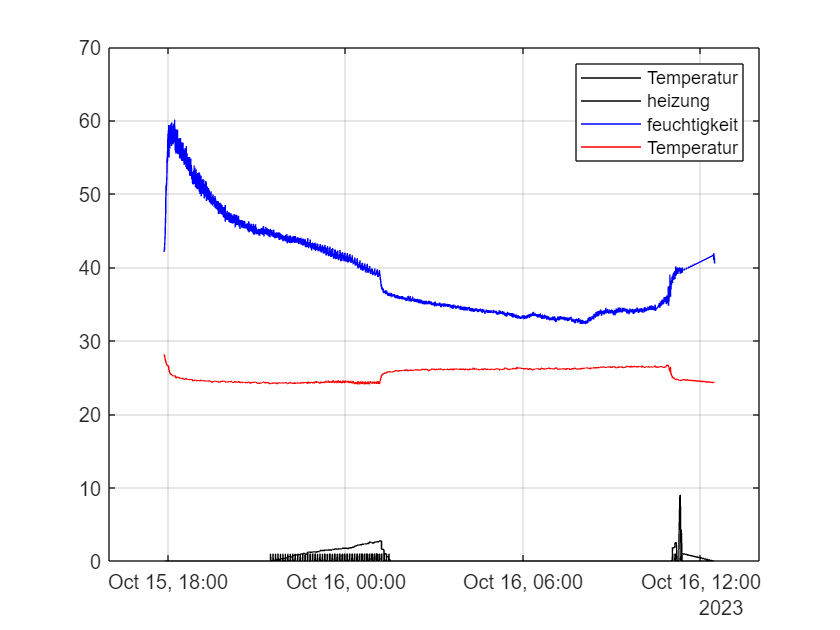

S= timerange(datetime("28-09-2023 12:00:00","InputFormat","dd-MM-yyyy HH:mm:ss"),a.datetime(end));
%a = a(S,:);
a.Properties.VariableNames;
 
plot(a.datetime ,a.relay_AC_3,'k')
hold on
plot(a.datetime ,a.T_Regler_Output*10,'k')

plot(a.datetime ,a.Humidity,'blue')
plot(a.datetime,a.Temperatur,'red')
legend("Temperatur","heizung","feuchtigkeit","Temperatur")
grid on

hold off

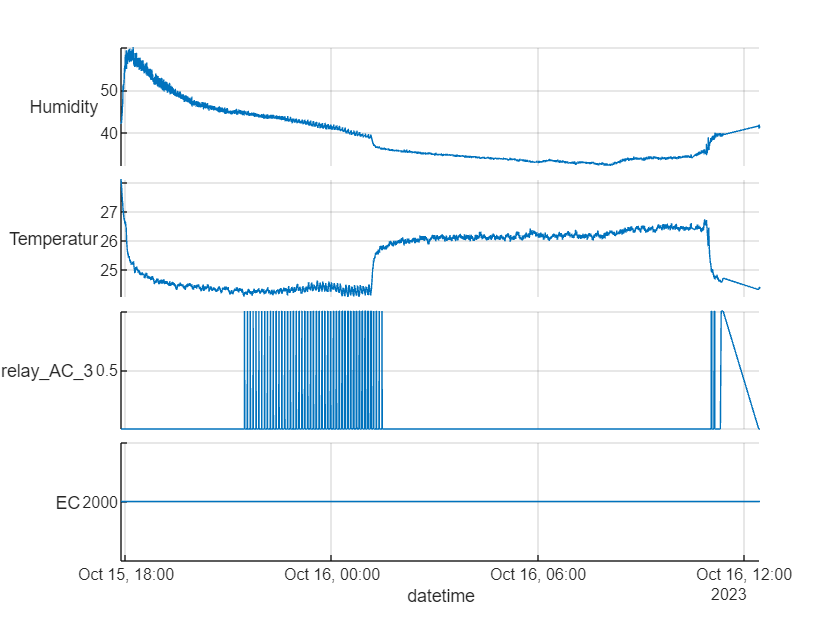


S= timerange(datetime("28-09-2023 12:00:00","InputFormat","dd-MM-yyyy HH:mm:ss"),a.datetime(end));
stackedplot(a(S,:),{'Humidity','Temperatur','relay_AC_3','EC'})
grid on


set = a(S,:);


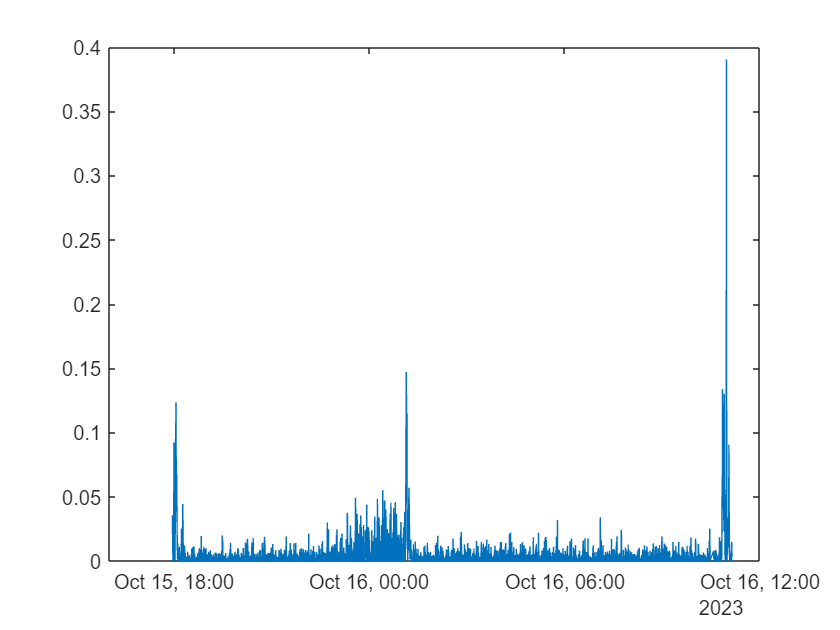


N = 600;
dat = set.Temperatur;

filter = ones(1,N)*1/N;

d = dat(ceil(N/2):end-floor(N/2));

mean = conv(dat,filter,"valid");

loc_var = (d-mean).^2;
plot(set.datetime(ceil(N/2):end-floor(N/2)), loc_var)


for i = 1:length(dat)
end

    












